times=1000;
snr=1:12;
snr=10*log10(snr)

snr =                    0   3.010299956639812   4.771212547196624   6.020599913279624   6.989700043360188   7.781512503836437   8.450980400142567   9.030899869919436   9.542425094393248  10.000000000000000  10.413926851582250  10.791812460476249


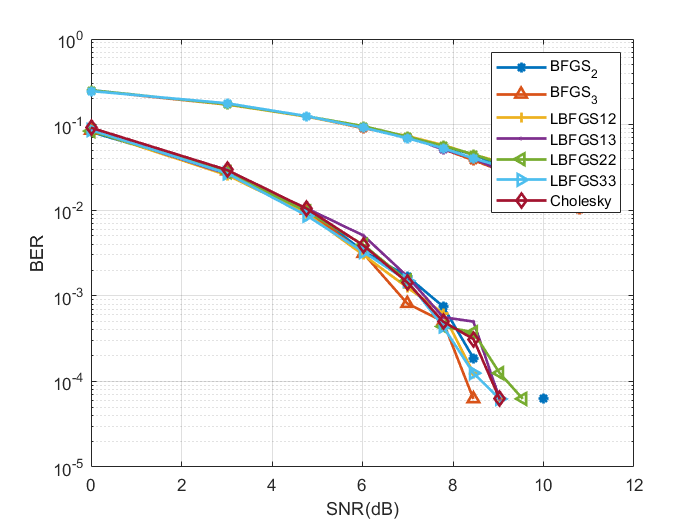

h1=semilogy(snr,BFGS2/1000,"LineWidth",1.6,"Marker","*");
xlabel('SNR(dB)')
ylabel("BER")
hold on;
grid ON
h2=semilogy(snr,BFGS3/1000,"LineWidth",1.6,"Marker","^");
h3=semilogy(snr,LBFGS_1_2/1000,"LineWidth",1.6,"Marker","+");
h4=semilogy(snr,LBFGS_1_3/1000,"LineWidth",1.6,"Marker",".");
h5=semilogy(snr,LBFGS_2_2/1000,"LineWidth",1.6,"Marker","<");
h6=semilogy(snr,LBFGS_3_3/1000,"LineWidth",1.6,"Marker",">");
%  semilogy(snr,CG,"LineWidth",1.6,"Marker",".")
%  semilogy(snr,SPCG,"LineWidth",1.6,"Marker","<")
 h7=semilogy(snr,inv/1000,"LineWidth",1.6,"Marker","diamond");
 semilogy(snr,BFGS2_16/1000,"LineWidth",1.6,"Marker","*")
 semilogy(snr,BFGS3_16/1000,"LineWidth",1.6,"Marker","*")
 semilogy(snr,LBFGS_1_2_16/1000,"LineWidth",1.6,"Marker","*")
 semilogy(snr,LBFGS_1_3_16/1000,"LineWidth",1.6,"Marker","*")
 semilogy(snr,LBFGS_2_2_16/1000,"LineWidth",1.6,"Marker","*")
 semilogy(snr,LBFGS_3_3_16/1000,"LineWidth",1.6,"Marker","*")
 legend([h1,h2,h3,h4,h5,h6,h7],"BFGS_2","BFGS_3","LBFGS12","LBFGS13","LBFGS22","LBFGS33",'Cholesky');